#  Relatório de Atividade - Regulador auto-ajustável

*Débora Nunes Pinto de Oliveira*

*Prof. Antonio Marcus, Análise e Projeto de Sistemas de Controle 21.1*

*15 de Maio de 2021*

Esse documento tem por objetivo descrever um *Self Tuning Regulator *(STR). Esse algoritmo determina uma convergência de um controlador adaptativo para um **processo linear e invariante no tempo**. Nesse trabalho, será considerado que a planta possuí uma única entrada e uma única saída. Também será definido que a frequência do laço de estimação é a mesma do controlador. Por fim, será utilizado o método de mínimos quadrados para estimar os parâmetros do processo e o algoritmo de localização determinística dos polos para o projeto da lei de controle. 

## **Fundamentação Teórica**

Um processo linear de única entrada e única saída (SISO, *Single Input - Single Output*) pode ser matematicamente expresso como:


$$Ay(t)=B\big(u(t)+v(t)\big)$$


para $y$ a saída do sistema, $u$ a entrada do processo e $v$ um distúrbio qualquer. Por sua vez, $A$ e $B$ são polinômios primos relativos em função do operador de atraso $q^{-1}$. Tendo em vista que as funções de transferência $Y(s)/U(s)$ e $Y(s)/V(s)$ caracterizam um sistema causal, é evidente que, se $\deg A =n$, obtém-se $\deg B = \deg A-d_0 =m$, para $d_0$ o "excesso" de polos do denominador $A$ em relação ao numerador $B$. É importante destacar que o polinômio $A$ é mônico. 

A malha de realimentação para um controlador generalizado pode ser expressa como:


$$Ru(t) = Tu_c(t)-Sy(t)$$


para $R$, $T$ e $S$ polinômios e $u_c$ o sinal de referência para o controlador. Similarmente, para garantir um controlador causal, é claro que $\deg S \leq \deg R$ e $\deg T \leq \deg R$. 

Substituindo a função da malha de realimentação na equação do processo, obtém-se o sistema em malha fechada descrito por:


$$y(t) = \frac{BT}{AR+BS}u_c(t)+ \frac{BR}{AR+BS}v(t)$$



$$u(t) =  \frac{AT}{AR+BS}u_c(t)- \frac{BS}{AR+BS}v(t)$$


É evidente que o polinômio característico da malha fechada é $A_c = AR+BS$. Essa equação é denominada "Equação Diophantina" e possui infinitas soluções para $R$ e $S$ caso os polinômios $A$ e $B$ não compartilhem fatores comuns, isto é, caso sejam primos relativos. Considerando que o $A$ possui maior ordem que $B$, a ordem de $R$ é definida como $\deg R = \deg A_c - \deg A$.

Para determinar o polinômio $T$ não incluso na equação Diophantina, é preciso especificar a função de transferência da saída $y_m(t)$em malha fechada em relação ao sinal de referência $u_c(t)$ tal como:


$$\frac{BT}{AR+BS} = \frac{BT}{A_c}  = \frac{B_m}{A_m}$$


O polinômio $B$ pode ser fatorado em $B^+B^-$, para $B^+$ um polinômio mônico com os zeros de $B$ bem amortecidos que podem ser cancelados com os polos do controlador, e $B^-$ um polinômio com os zeros não amortecidos de $B$ que não podem ser cancelados com polos do controlador. 

Logo, o polinômio $B_m$ deve conter o fator $B^-$ tal como $B_m = B^-B_m^{'}$. Além disso, o polinômio $A_c$ deve conter o fator cancelado $B^+$, tal como $A_c = A_0\,A_m\,B^+$. Como $B^+$ é fator de $B$ e $A_c$ mas não é fator de $A$, é evidente que $B^+$ deve ser fator de $R$, o qual é descrito como $R = B^+R^{'}$. 

Logo, determina-se o polinômio $T$ como:


$$\frac{B^+B^-T}{A_0\,A_m\,B^+} = \frac{B^-B_m^{'}}{A_m} \rightarrow T = A_0\,B_m^{'}$$


Dessa forma, a equação Diophantina pode ser reescrita como:


$$A_c^{'} = A_0\,A_m = AR^{'} + B^-S$$


Essa equação garante que, para determinado controlador definido pelos polinômios $R$, $S$ e $T$, a resposta em malha fechada do processo $A$ e $B$ é conforme o comportamento de $A_m$ e $B_m$. A nova formulação de da equação Diophantina possuí infinitas soluções para $R = R_0+QB$ e $S=S_0-QA$ para $Q$ um polinômio qualquer. Neste trabalho, será buscada a solução para o controlador de menor grau. Sendo assim, tem-se que $\deg S \leq \deg A -1$. Logo, pode-se obter as seguintes restrições para garantir a causalidade do controlador:


$$\deg S \leq \deg R \rightarrow \deg A-1 \leq \deg A_c - \deg A \therefore 2\deg A -1 \leq \deg A_c$$



$$\deg T \leq \deg R \rightarrow \deg A_0 + \deg B_m^{'} \leq \deg A_0+\deg A_m+\deg B^+ - \deg A \therefore \deg A -\deg B^+ \leq \deg A_m - \deg B_m^{'} $$


Somando o fator $\deg B^-$ em ambos os lados da última inequação, obtém-se que:


$$d_0 = \deg A -\deg B \leq \deg A_m - \deg B_m$$


Como o controlador é discreto, é necessário que todos os polinômios $R$, $S$ e $T$ representem o mesmo atraso, e, portanto, possuam o mesmo grau. Dessa forma, tem-se que:


$$\deg R = \deg A_0 + \deg A_m + \deg B^+ - \deg A = \deg S = \deg A - 1$$


Considerando que foi encontrado o modelo de mínima ordem do processo em malha fechada, isto é, $\deg A_m = \deg A$, pode-se encontrar que:


$$\deg A_0 = \deg A - \deg B^+-1 $$


É evidente que o algoritmo apresentado é puramente algébrico e pode ser aplicado tanto em sistemas contínuos quanto processos discretos.

## Desenvolvimento

Os controladores propostos foram construídos e simulados utilizando blocos no Simulink. As estratégias adotadas seguem a apresentação citada na Seção 1. Primeiramente, serão apresentados os exercícios resolvidos. Por fim, serão discutidas as questões propostas.

### Exemplo 1: STR com cancelamento de zeros

Para este exemplo, será considerado o processo contínuo $G(s)$ tal que seu equivalente discreto $H(q)$ é expresso por:


$$H(q) = \frac{B(q)}{A(q)} = \frac{b_0q+b_1}{q^2+a_1q+a_2}$$


Sendo assim, é claro que $\deg A = 2$ e $\deg B=1$. É possível aplicar que $B^- = b_0$ e $B^+ = \frac{B}{B^-} =  q+\frac{b_1}{b_0}$. Dessa forma, o único zero de $B$ é parcela de $B^+$ e, portanto, cancelado por um polo do controlador $A_c$. Sabendo que a resposta esperada em malha fechada é dada por:


$$H_m(q)=\frac{B_m(q)}{A_m(q)} =\frac{b_{m0}\, q}{q^2+a_{m1}q+a_{m2}} $$


Tem-se que, $B_m' = \frac{B_m}{B^-} =\frac{b_{m0}\,q}{b_0}$. Como $\deg S = \deg A -1 = 1$ e $\deg R = \deg S = 1$, é evidente que $\deg R^{'} = \deg R - \deg B^{+} = 0$. Logo, como $R^{'}$ é mônico, $R^{'}=1$. Como $\deg Am = \deg A$ e $\deg B^+ = \deg B$, obtém-se que $\deg A_0 = \deg A -\deg B -1 = 0$. Logo, pode-se definir que $A_0 = 1$. 

A equação Diophantina é, então, escrita como:


$$q^2+a_{m1}q+a_{m2} = (q^2+a_1q+a_2) + b_0\,S$$


Como $\deg S =1$, é possível representar $S = s_0q+s_1$. Dessa forma, tem-se que:

$s_0 = \frac{a_{m1}-a_1}{b_0}$ e $s_1 = \frac{a_{m2}-a_2}{b_0}$

Logo, conclui-se que $R = B^+ = q+\frac{b_1}{b_0}$, $S =\frac{(a_{m1}-a_1)q+(a_{m2}-a_2)}{b_0}$ e $T = B^{'}_m = \frac{b_{m0}\,q}{b_0}$. 

Para que o fator $B^+$ e seja cancelado pelo polinômio característico do controlador $A_c$, é necessário que o zero de $B^+$ seja fortemente amortecido. Caso contrário, o polo do controlador discreto se aproxima da instabilidade. Em casos de zeros pouco amortecidos em $B$, esses fatores devem ser considerados no fator $B^-$, como descrito no Exemplo 2. 

### Exemplo 2: STR sem cancelamento de zeros

Para este exemplo, será considerado o processo contínuo $G(s)$ tal que seu equivalente discreto $H(q)$ é expresso por:


$$H(q) = \frac{B(q)}{A(q)} = \frac{b_0q+b_1}{q^2+a_1q+a_2}$$


Sendo assim, $\deg A = 2$ e $\deg B=1$. É possível aplicar que $B^- = b_0q+b_1$ e $B^+ = \frac{B}{B^-} =  1$. Dessa forma, o único zero de $B$ é parcela de $B^-$ e, portanto, não cancelado por um polo do controlador $A_c$. Sabendo que a resposta esperada em malha fechada é dada por:


$$H_m(q)=\frac{B_m(q)}{A_m(q)} = \frac{\beta(b_{0}\, q+b_{1})}{q^2+a_{m1}q+a_{m2}} = \frac{b_{m0}\, q+b_{m1}}{q^2+a_{m1}q+a_{m2}} $$


para $B_m' = \frac{B_m}{B^-}= \beta$. Como $\deg S = \deg A -1 = 1$ e $\deg R = \deg S = 1$, é evidente que $\deg R^{'} = \deg R - \deg B^{+} = 1$. Logo, como $R^{'}$ é mônico, tem-se que$R^{'}=q+r_1$. Como $\deg A_m = \deg A$, obtém-se que $\deg A_0 = \deg A -\deg B^+ -1 = 1$. Logo, pode-se representar que $A_0 = q+a_0$. Analogamente, como $\deg S =1$, é possível representar $S = s_0q+s_1$.

A equação Diophantina é então escrita como:


$$(q+a_0)(q^2+a_{m1}q+a_{m2}) = (q^2+a_1q+a_2)(q+r_1) + (b_0 q +b_1)(s_0q+s_1)$$


 Adotando $q=-b_1/b_0$, é possível encontrar que


$$r_1 = \frac{(a_0+a_{m1}-a_1)b_1^2+(a_2-a_{m2}-a_0a_{m1})b_0b_1 + (a_0a_{m2})b_0^2}{b_1^2-a_1b_0b_1+a_2b_0^2}$$


Se $A(q)$ e $B(q)$ possuírem algum fator em comum, o denominador de $r_1$ é nulo. Entretanto, essa condição invalida a premissa considerada pela equação Diophantina que os polinômios $A$ e $B$ são primos relativos. 

Conhecendo $r_1$, é possível definir as constantes $s_0$ e $s_1$. Pelo extensivo equacionamento para equivalência das potências de $q$ em ambos os lados da equação Diophantina, esse resultado pode ser encontrado na equação 3.21 da bibliografia. Por fim, tem-se que $T = B_m^{'}A_0 = \beta(q+a_0)$.

Os métodos aplicados no Exemplo 1 e Exemplo 2 podem ser utilizados com funções de transferência contínuas, tal como apresentado no Exemplo 3.

### Exemplo 3: STR contínuo no tempo

Para este exemplo, será considerado o processo contínuo $G(s)$ expresso por:


$$G(s) = \frac{B(s)}{A(s)} = \frac{b}{s^2+as}$$


Sendo assim, $\deg A = 2$ e $\deg B=1$. É possível aplicar que $B^- = b$ e $B^+ = \frac{B}{B^-} =  1$. Sabendo que a resposta esperada em malha fechada é dada por:


$$H_m(s)=\frac{B_m(s)}{A_m(s)} = \frac{\omega^2}{s^2+2\zeta\omega s+\omega^2}$$


para $B_m'  = \frac{B_m}{B^-} = \frac{\omega^2}{b}$. Como $\deg S = \deg A -1 = 1$ e $\deg R = \deg S = 1$, é evidente que $\deg R^{'} = \deg R - \deg B^{+} = 1$. Logo, como $R^{'}$ é mônico, tem-se que$R^{'}=s+r_1$. Como $\deg A_m = \deg A$, obtém-se que $\deg A_0 = \deg A -\deg B^+ -1 = 1$. Logo, pode-se representar que $A_0 = s+a_0$. Analogamente, como $\deg S =1$, é possível representar $S = s_0s+s_1$.

A equação Diophantina é então escrita como:


$$(s+a_0)(s^2+2\zeta\omega s+\omega^2) = (s^2+as)(s+r_1) + b(s_0s+s_1)$$


Expandindo as multiplicações, obtém-se:


$$s^3+s^2(2\zeta\omega +a_0)+s(\omega^2+2a_0\zeta\omega)+a_0\omega^2 = s^3+s^2(a+r_1)+s(ar_1+bs_0)+bs_1$$


Aplicando a equivalência dos fatores multiplicativos das das potências de $q$ ambos os lados da equação Diophantina, tem-se que:

$r_1 = 2\zeta\omega+a_0-a$, $s_0 = \frac{\omega^2+2a_0\zeta\omega-ar_1}{b}$ e $s_1 = \frac{a_0\omega^2}{b}$ 

para $b\neq 0$. Por fim, $T = B_m^{'}A_0 = \frac{\omega^2(s+a_0)}{b}$.

Analisando este exemplo, é evidente que o polinômio $A_0\neq 1$ para solução de mínimo grau quando há zeros não cancelados do processo, ou seja, se $B^-\neq b_0$. Esse polinômio $A_o$ representa a dinâmica do observador, o qual deve ser cancelado na função de transferência entre o sinal de comando $u_c$ e a saída do processo $y$. Aplicando a equação Diophantina sobre a fração $T/R$, encontra-se que:


$$\frac{T}{R} = \frac{A_0B_m^{'}}{R} = \frac{(AR^{'}+B^-S)B^{'}_m}{A_mR} = \frac{AB_m}{BA_m}+\frac{SB_m}{RA_m}$$


Dessa forma, a lei de controle é reescrita como:


$$u = \frac{T}{R}u_c - \frac{S}{R}y = \frac{AB_m}{BA_m}u_c+\frac{SB_m}{RA_m}u_c - \frac{S}{R}y = \frac{AB_m}{BA_m}u_c - \frac{S}{R}(y_m-y)$$


Como $\deg B < \deg A$ para um processo causal, a função de transferência $A/B$ não é realizável. Além disso, caso o sistema seja de fase não mínima, isto é, se os zeros de $B$ estão no semi-plano direito de $s$, a função de transferência $A/B$ é instável. Entretanto, a combinação em cascata do modelo de referência $B_m/A_m$ e a inversa do processo $A/B$ é realizável se $\deg T \leq \deg R$, uma vez que, conforme apresentado na Seção 1, a causalidade da lei de controle garante que $d_0 = \deg A -\deg B \leq \deg A_m - \deg B_m$. 

Tendo em vista que o termo $\frac{AB_m}{BA_m}$ representa a malha de *feedfoward* e está separada da função de transferência de realimentação $\frac{S}{R}$, a cascata do modelo de referência e inversa do processo podem apresentar termos não lineares sem prejudicar a estabilidade da malha fechada.

### Exemplo 4: Regulador indireto adaptativo com cancelamento de zeros discreto

Caso a função de transferência do processo $B/A$seja desconhecida, é possível estimá-la pelo método dos mínimos quadrados antes de aplicar os coeficientes $a_n$ e $b_n$ na equação Diophantina. Esse método é denominado regulador adaptativo indireto, uma vez que os parâmetros do controlador não são atualizados diretamente, mas alterados conforme a estimativa do modelo do processo.

Para tal, considera-se que o modelo do processo pode ser escrito como:


$$y(t) = -a_1y(t-1) - \cdots - a_ny(t-n) + b_0u(t-d_0) + \cdots +b__mu(t-d_0-m) = \varphi^T(t-1)\theta$$


para $\theta = [a_1\cdots\; a_n\; b_0 \cdots\; b_m]$e $\varphi^T(t-1) = [-y(t-1) \cdots\; y(t-n)\; u(t-d_0)\cdots\; u(t-d_0-m)]$. Conforme descrito na Atividade 2, o método dos mínimos quadrados recursivo é expresso como:


$$\hat{\theta}(t) = \hat{\theta}(t-1)+K(t)\varepsilon(t)$$


para $\varepsilon = y(t)-\varphi^T(t)\hat{\theta}(t-1)$, $K(t) = P(t-1)\varphi(t-1)\big(\lambda + \varphi^T(t-1)P(t-1) \varphi(t-1)\big)^{-1}$ e $P(t) = \big(I-K(t)\varphi^T(t-1)P(t-1)\big)/\lambda$. Após estimar os coeficientes em $\theta$ referentes aos polinômios $A$ e $B$, pode-se aplicar a equação Diophantina conforme a especificação da malha fechada $B_m/A_m$ e do polinômio observador $A_0$. Esse processo deve ser repetido a cada passo de amostragem. 

Na Figura 1, está ilustrado o sinal de saída do processo $y_m(t)$ em malha fechada e o sinal de referência $u_c(t)$ para uma função de malha fechada $H_m(q)$ tal que:


$$H_m(q) = \frac{B_m}{A_m}=\frac{0.1761q}{q^2-1.3205q+0.4966}$$


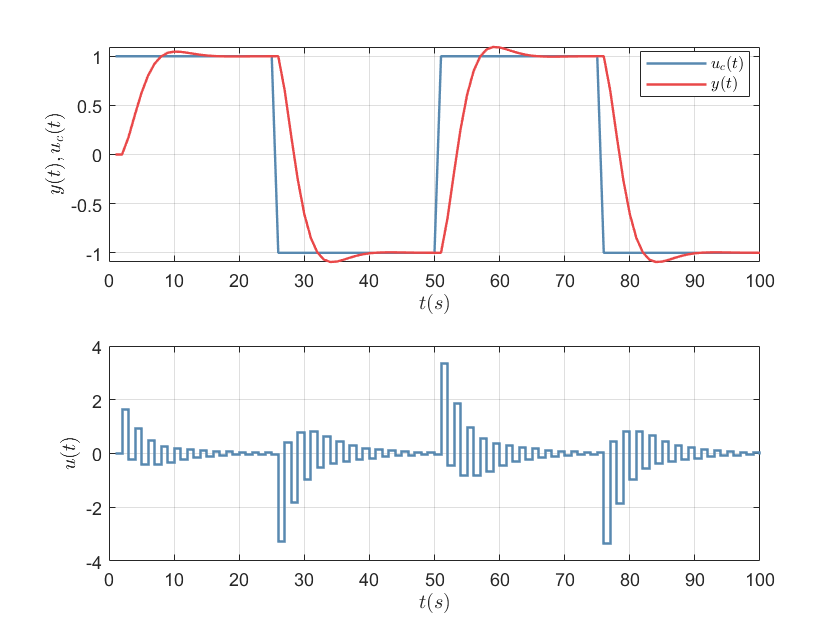

epex4_1

***Figura 1*****: ***Sinal de saída da malha fechada *$y_m(t)$*, de referência *$u_c(t)$* e de controle *$u(t)$*. *

Conforme descrito no Exemplo 1, a lei de controle generalizada conforme os polinômios da equação Diophantina para o cancelamento de todos os zeros do processo com os polos do controlador é escrita como:


$$u(t) = t_0u_c(t)-s_0y(t)-s_1y(t-1)-r_1u(t-1)$$


Esse sinal de controle $u(t)$ para o sinal de saída $y_m(t)$ e de referência $u_c(t)$ também está ilustrado na Figura 1. Observando a Figura 1, é evidente uma oscilação no sinal de controle $u(t)$. Essa variação é decorrente do cancelamento de um zero pouco amortecido do processo. 

Em seguida, empregou-se o método dos mínimos quadrados recursivos (RLS) para a estimativa do processo em malha aberta. A função de transferência em malha aberta $H(q)$é descrita por:


$$H(q) = \frac{B}{A} = \frac{b_0q+b_1}{q^2+a_1q+a^2}$$
 

Na Figura 2, está ilustrada a estimativa dos parâmetros $\hat{\theta} = [a_1\, a_2\, b_0\, b_1]$ empregando RLS.

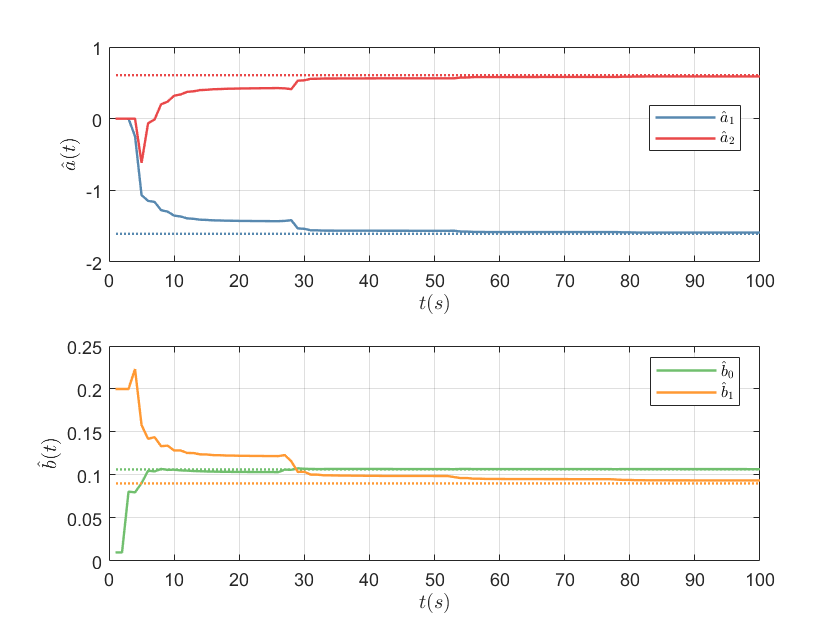

epex4_2

***Figura 2*****: ***Estimativa dos parâmetros *$\hat{\theta}$ *do processo *$H(q)$*. *

Observando a Figura 2, é evidente a convergência do modelo estimado em relação aos parâmetros reais do processo em malha aberta. Conforme descrito no algoritmo, a cada passo de amostragem também são estimados os coeficientes $r_n$, $s_n$ e $t_n$ dos polinômios da lei de controle. Essa estimativa está ilustrada na Figura 3.

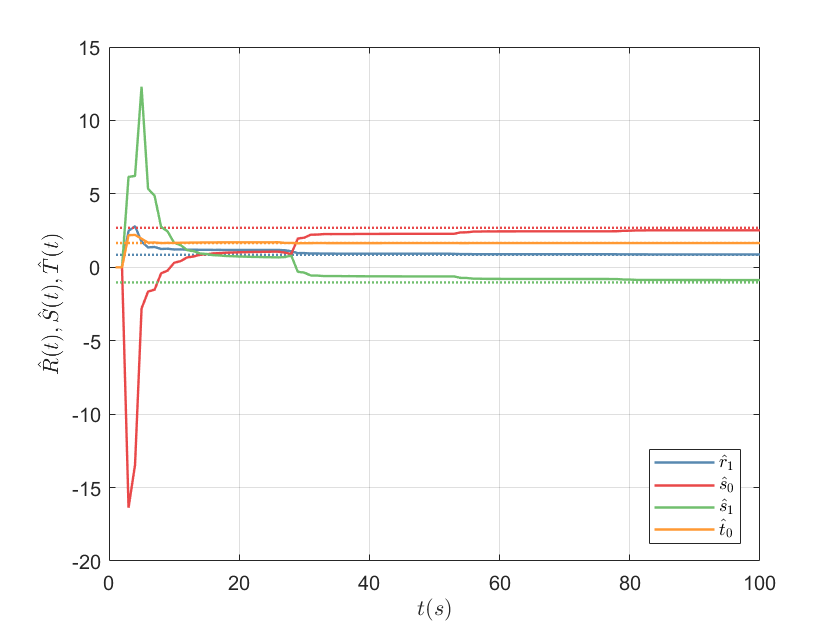

epex4_3

***Figura 3*****: ***Estimativa dos coeficientes dos polinômios *$R$, $S$ *e *$T$.

Observando a Figura 3, é possível concluir que os coeficientes de $R$, $S$ e $T$ convergem para os valores projetados. Com o intuito de evitar a oscilação do sinal de controle $u(t)$, pode-se aplicar a formulação sem cancelamento de zeros do processo apresentada no Exemplo 2. Essa alteração será apresentada no Exemplo 5 a seguir.

### Exemplo 5: Regulador indireto adaptativo sem cancelamento de zeros discreto

Para esse exemplo, será considerada a função em malha fechada $H_m(q)$ tal que:


$$H_m(q) = \frac{B_m}{A_m}=\frac{0.0953q+0.0808
}{q^2-1.3205q+0.4966}$$


Conforme descrito no Exemplo 2, para a definição de $B^+=1$, é necessário considerar $A_0=q+a_0$. Neste exemplo, será definido que $a_0=0$. O sinal de controle $u(t)$, o sinal de saída $y_m(t)$ e o sinal de referência $u_c(t)$ estão ilustrados na Figura 4.

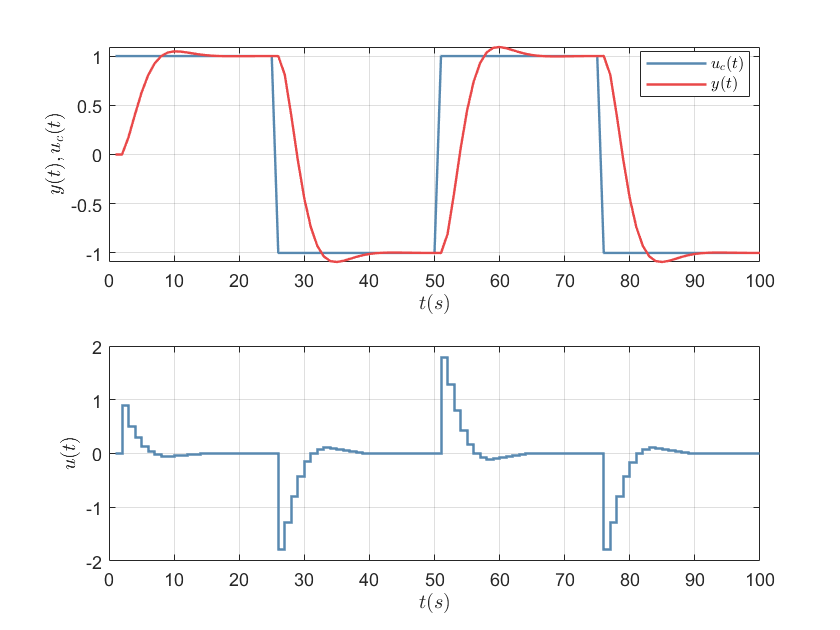

epex5_1

***Figura 4*****: ***Sinal de saída da malha fechada *$y_m(t)$*, de referência *$u_c(t)$* e de controle *$u(t)$*. *

Observando a Figura 4, é evidente a ausência da oscilação em $u(t)$ assim como apresentado na Figura 1. Essa modificação é justificada pelo não cancelamento dos zeros pouco amortecidos do processo. Analogamente ao exemplo anterior, na Figura 5, está ilustrada a estimativa dos parâmetros $\hat{\theta} = [a_1\, a_2\, b_0\, b_1]$ empregando RLS.

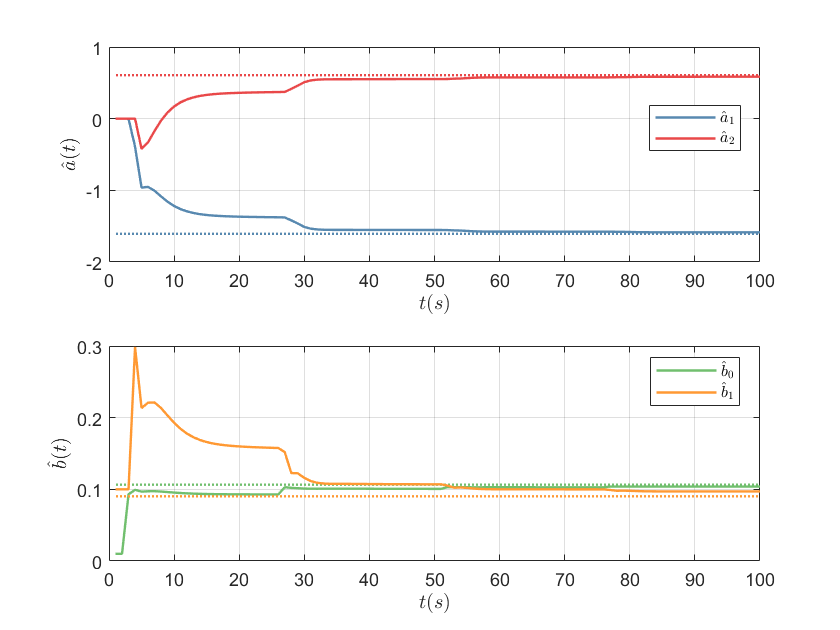

epex5_2

***Figura 5*****: ***Estimativa dos parâmetros *$\hat{\theta}$ *do processo *$H(q)$*. *

Observando a Figura 5, é clara a convergência do modelo estimado em relação aos parâmetros reais $a_n$ e $b_n$ do processo em malha aberta. Conforme descrito no algoritmo, a cada passo de amostragem também são estimados os coeficientes $r_n$, $s_n$ e $t_n$ dos polinômios da lei de controle. Essa estimativa está ilustrada na Figura 6.

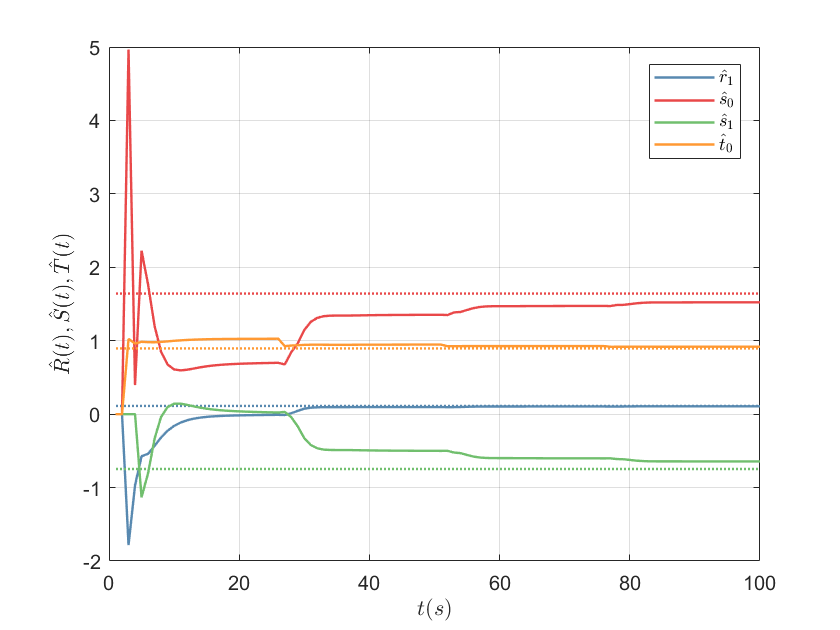

epex4_3

***Figura 6*****: ***Estimativa dos coeficientes dos polinômios *$R$, $S$ *e *$T$.

Observando a Figura 6, é possível observar que os coeficientes de $R$, $S$ e $T$ convergem para os valores projetados com um erro de regime permanente não nulo. Esse mesmo algoritmo para a estimativa de um controlador adaptativo indireto pode ser aplicado sobre modelos contínuos, assim como descrito no Exemplo 6.

### Exemplo 6: Regulador indireto adaptativo sem cancelamento de zeros no domínio contínuo

Para esse exemplo, será considerada a função em malha fechada $G_m(s)$ e aberta $G(s)$ tal que:

$G_m(s) = \frac{B_m}{A_m}=\frac{1
}{s^2+0.14s+1}$ e $G(s)=\frac{1}{s^2+s}$

Conforme descrito no Exemplo 3, para a definição de $B^+=1$, é necessário considerar $A_0=q+a_0$. Neste exemplo, será definido que $a_0=2$. O sinal de controle $u(t)$, o sinal de saída $y_m(t)$ e o sinal de referência $u_c(t)$ estão ilustrados na Figura 7.

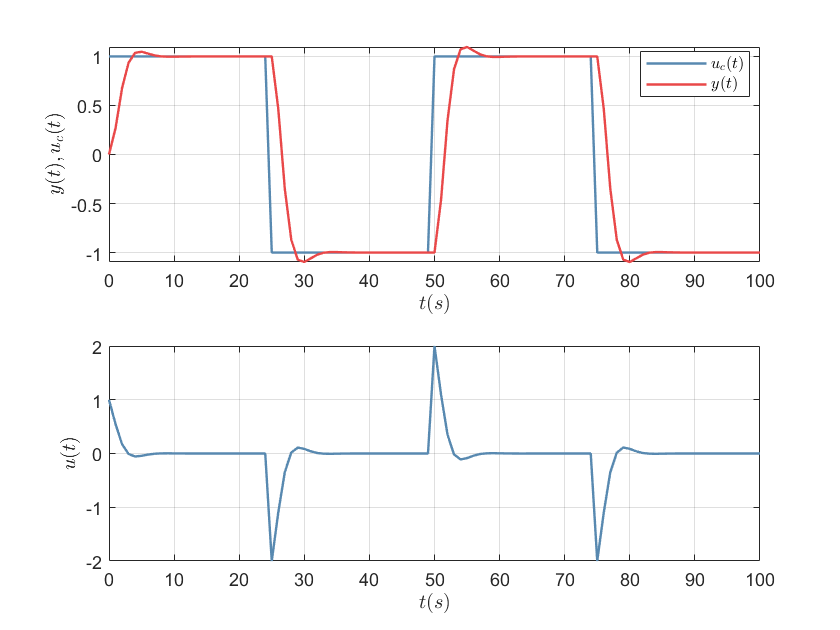

epex6_1

***Figura 7*****: ***Sinal de saída da malha fechada *$y_m(t)$*, de referência *$u_c(t)$* e de controle *$u(t)$*.*

A função de transferência estimada para o processo pelo método de mínimos quadrados recursivo é:

epex6_2

Gc =
 
     -0.0506 s + 0.8209
  ------------------------
  s^2 + 1.355 s + 0.002332
 
Continuous-time transfer function.



É evidente que, comparando com o numerador $b=1$ da função $G(s)$ real do modelo, há o surgimento de um polinômio de primeiro grau $b_0s+b_1$ no numerador da função de transferência estimada. Essa diferença é decorrente da conversão do modelo discreto em contínuo para o período de amostragem simulado, isto é, há um erro numérico. Na Figura 8, está ilustrada, respectivamente, a resposta $y_m(t)$ e $y_e(t)$ do processo real e estimado no domínio discreto em malha fechada.

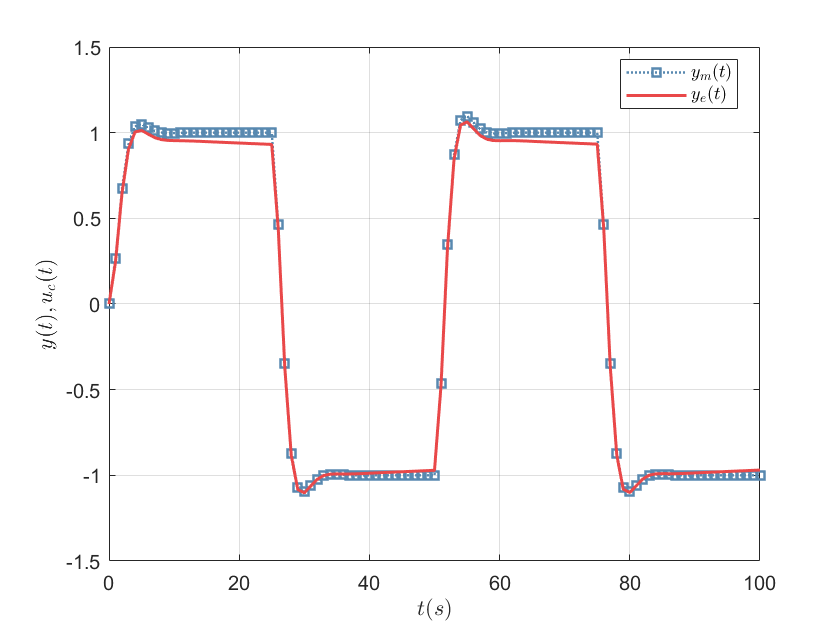

epex6_3

***Figura 8*****: ***Sinal de saída da malha fechada *$y_m(t)$ *e estimada *$y_e(t)$* via RLS.*

Observando a Figura 8, é evidente que a estimativa dos parâmetros da da função de transferência discreta está correta. O erro médio quadrático entre a curva estimada e $y_m(t)$ é aproximadamente $0.0013$.

### Exemplo 7: Regulador adaptativo direto para d0=1

É possível obter uma nova formulação da equação Diophantina multiplicando ambos os termos por $y(t)$. Dessa forma:


$$A_0A_my(t) = AR^{'}y(t)+B^-Sy(t)$$


Substituindo $Ay(t) = Bu(t)$, caso o distúrbio sobre a saída $v(t)=0$, e considerando que $R{'}B = RB^{-}$, obtém-se que:


$$A_0A_my(t)=BR{'}u(t) + B^-Sy(t) = B^-\big(Ru(t)+Sy(t)\big)
$$


Esse equacionamento pode ser considerado como um novo modelo do processo, uma vez que relaciona a saída $y(t)$ com a entrada $u(t)$. Logo, a estimativa dos coeficientes dos polinômios $R$ e $S$ projeta uma lei de controle sem necessidade da busca dos parâmetros da planta. Esse método é nomeado controlador adaptativo direto, uma vez que é dispensável a estimativa do modelo da planta. É importante destacar, na nova equação do modelo, a não linearidade introduzida pelo termo $B^-$, caso $B^-\neq b_0$.

Se $B^-=b_0$ e todos os zeros do processo são bem amortecidos, tem-se que:


$$A_0A_my(t)= b_0\big(Ru(t)+Sy(t)\big) = \tilde{R}u(t) + \tilde{S}y(t) \therefore y(t) = \frac{\tilde{R}u(t) + \tilde{S}y(t)}{A_0A_m}
$$


para $\tilde{R}=b_0R$ e $\tilde{S} = b_0S$. É importante destacar que $\tilde{R}$ não é mônico. O vetor $\theta$ de parâmetros estimados e o vetor $\varphi$ dos sinais de regressão podem ser descritos como $\theta = [r_0\cdots\, r_i\; s_0\cdots\, s_i]$ e $\varphi= [u(t)\cdots\, u(t-i)\; y(t)\cdots\, y(t-1)]$. Por sua vez, a quantidade de parâmetros $2(i+1)$ do vetor $\theta$ é definida para $i=\deg(A_0A_m)-d_0$. Sendo assim, além de especificar o polinômio $H_m(q)$ e $A_0$ da dinâmica em malha fechada e do observador, respectivamente, é necessário especificar o grau $d_0=\deg{A}-\deg{B}$. 

Considerando o sistema apresentado na Figura 1, é possível estimar diretamente os parâmetros da lei de controle empregando RLS. Para a aplicação do algoritmo, foi considerado $d_0=1$ e $A_0=1$. Sendo assim, o modelo estimado é descrito por:


$$y(t) = r_0u(t-1)+r_1u(t-2)+s_0y(t-1)+s_1y(t-2)$$


Os parâmetros $\hat{r}_1$, $\hat{s}_0$ e $\hat{s}_1$ devem ser divididos por $\hat{r}_0$ para transformar os polinômios $\tilde{R}$ e $\tilde{S}$ nos polinômios $R$ e $S$, respectivamente, uma vez que $R$ é mônico. Além disso, $T=A_0Am=t_0q = 1+a_{m1}+a_{m2}$ para $\beta$ um ganho unitário. As estimativas dos coeficientes dos polinômios $R$, $S$ e $T$ estão ilustradas na Figura 9.

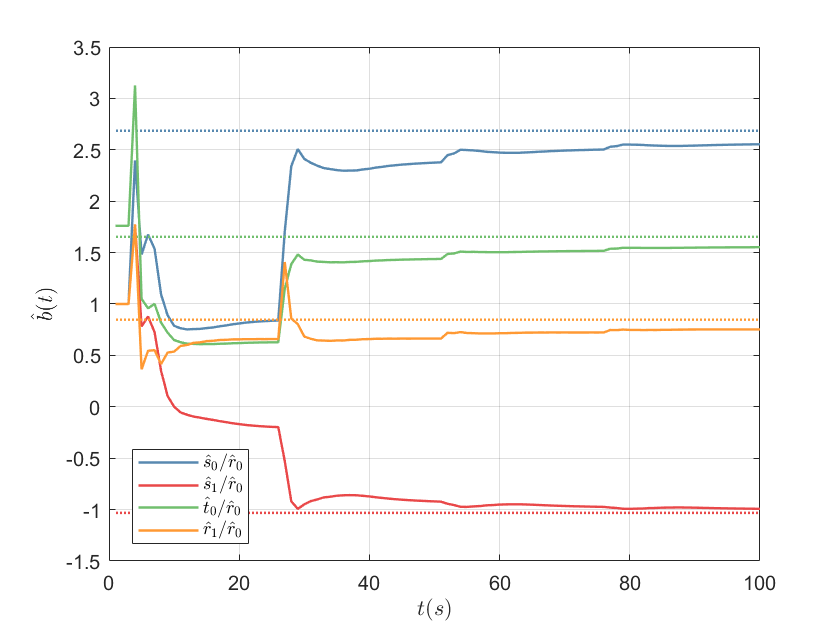

epex7_2

***Figura 9*****: ***Estimativa dos coeficientes dos polinômios *$R$, $S$ *e *$T$.

Observando a Figura 9, é possível concluir que os coeficientes de $R$, $S$ e $T$ convergem para os valores projetados. Esse mesmo algoritmo pode ser aplicado para $d_0\neq 1$, conforme apresentado no Exemplo 8 a seguir.

### Exemplo 8: Regulador adaptativo direto para d0=2

Considerando o sistema apresentado na Figura 4, é possível estimar diretamente os parâmetros da lei de controle empregando RLS. Para a aplicação do algoritmo, foi considerado por especificação de projeto $d_0=2$ e $A_0=1$. Sendo assim, o modelo estimado em malha fechada é descrito por:


$$y(t) = r_0u(t-2)+r_1u(t-3)+s_0y(t-2)+s_1y(t-3)$$


Assim como no Exemplo 7, $B^-=b_0$. Logo, os parâmetros $\hat{r}_1$, $\hat{s}_0$ e $\hat{s}_1$ devem ser divididos por $\hat{r}_0$ para transformar os polinômios $\tilde{R}$ e $\tilde{S}$ nos polinômios $R$ e $S$, respectivamente, uma vez que $R$ é mônico. Além disso, como $T=A_0Am=t_0q = 1+a_{m1}+a_{m2}$ para $\beta$ um ganho unitário. As estimativas dos coeficientes dos polinômios $R$, $S$ e $T$ estão ilustradas na Figura 10.

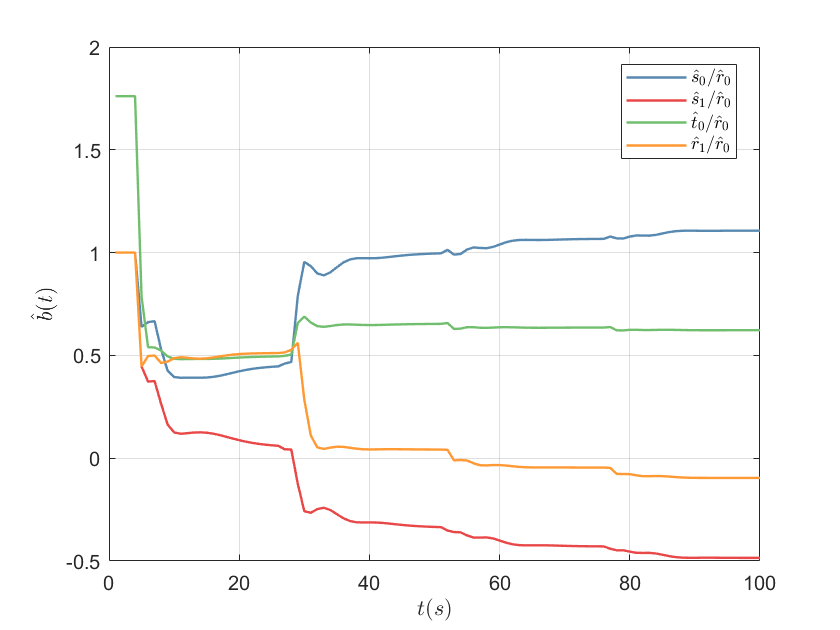

epex8_2

***Figura 10*****: ***Estimativa dos coeficientes dos polinômios *$R$, $S$ *e *$T$.

Observando a Figura 10, é possível observar que os coeficientes de $R$, $S$ e $T$ convergem para o intervalo de $N=100$ amostras. 

### Exemplo 9: Adição de distúrbios ao sinal de controle

Nesse exemplo, será considerada a adição de um distúrbio à entrada $u(t)$ do regulador indireto descrito no Exemplo 5. Essa pertubação é definida como $v(t)=0.5$, para $t\geq 40$. O sinal de controle $u(t)$, o sinal de saída $y_m(t)$ e o sinal de referência $u_c(t)$ estão ilustrados na Figura 11.

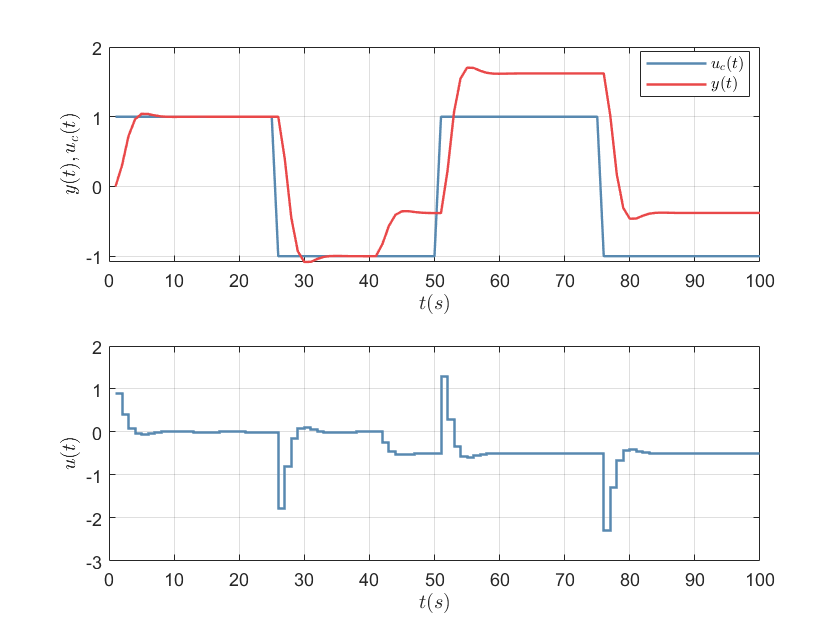

epex9_1

***Figura 11*****: ***Sinal de saída da malha fechada *$y_m(t)$*, de referência *$u_c(t)$* e de controle *$u(t)$*.*

Observando a Figura 11, é evidente que o erro em regime permanente é não nulo após a adição do distúrbio. 

Para a estimativa de parâmetros do processo por RLS, o fator de esquecimento foi definido como $\lambda=0.98$. Na Figura 12 estão apresentadas as estimativas para os parâmetros $\hat{\theta} = [a_1\, a_2\, b_0\, b_1]$.

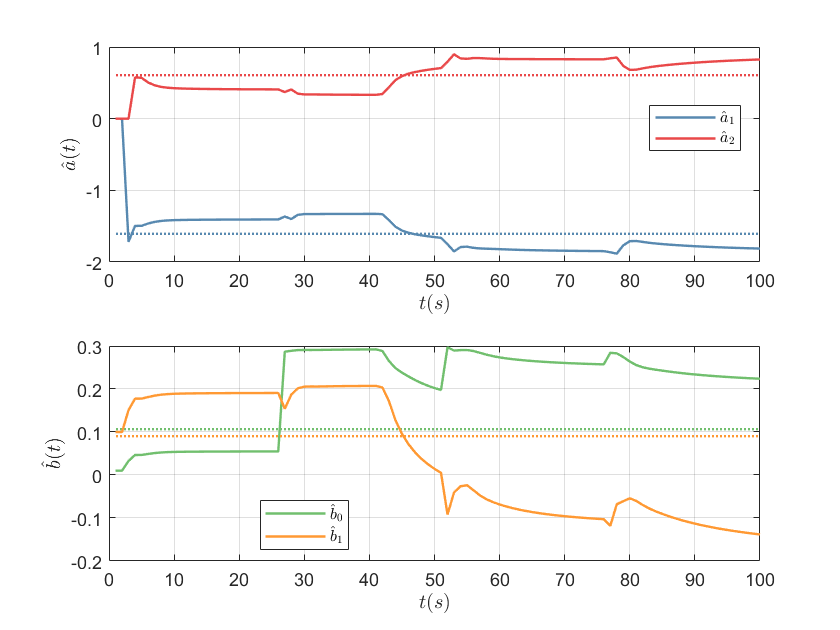

epex9_2

***Figura 12*****: ***Estimativa dos parâmetros *$\hat{\theta}$ *do processo *$H(q)$*. *

Observando a Figura 12, é evidente que a adição de um ruído em $t=40$ altera rapidamente os parâmetros estimados. Essa modificação indica ao algoritmo recursivo que a estimativa $\hat{\theta}(k)$ está incorreta e, portanto, maiores parcelas devem ser incrementadas à $\hat{\theta}(k)$ para obter $\hat{\theta}(k+1)$. Após a manutenção do sinal de controle $u(t)$ a partir de $t=60$, as estimativas convergem para um valor distante do real. 

A rejeição à perturbação pode ser adicionada ao modelo estimado de duas maneiras: primeiramente, pode-se incluir o modelo da perturbação, caso conhecida, ao modelo estimado; em segundo lugar, é possível filtrar o sinal de saída $y(t)$ e de entrada $u(t)$ do processo com um filtro $H_f(s)$ tal que a magnitude da perturbação seja reduzida. Esse último caso será descrito no Exemplo 10 a seguir.

### Exemplo 10: Rejeição de distúrbios no sinal de controle

Para rejeição do distúrbio $v(t)$caracterizado como $v(t)=0.5$ para $t\geq 40$, foi adotado um filtro $H_f(s)$cujo equivalente discreto é o polinômio $A_d(q)=q-1$. Dessa forma, o modelo estimado no Exemplo 9 pode ser reescrito como:


$$A_dAy(t) = A_dB\big(u(t)+v(t)\big) = A_dBu(t)+e(t)$$


para $e(t)=A_dv(t)$. Como o distúrbio $v(t)$ é um degrau, o erro $e(t)$é um pulso de magnitude $0.5$ em $t=40$. Considerando $y_f(t)=A_dy(t)$ e $u_f(t)=A_du(t)$, pode-se escrever o novo modelo como:


$$Ay_f(t)= Bu_f(t)+e(t)$$


Aplicando RLS, os parâmetros estimados são os coeficientes dos polinômios $A$ e $B$. Assim como, no estimador, acrescentou-se a parcela $A_m$; no controlador$A_c^0$, deve-se adicionar o fator $X$, tal que o novo polinômio característico $A_c=XA_c^0$. Caso $X=q+x_0$, é acrescentada um polo $-x_0
$ à malha fechada, isto é, uma ação integral para garantir erro nulo em regime permanente. Dessa forma, considera-se que a solução da equação Diophantine os polinômios $R$ e $S$ é:

$R = A_dR^{'} = XR^0+YB$ e $S  = A_dS^{'}= XR^0-YA$

para $R_0$ e $S_0$ as soluções da equação Diophantina para o polinômio característico $A_c^0$ e $Y=y_0$. Isolando o polinômio $Y$ para $q=1$, tem-se:


$$y_0=\frac{-(1+x_0)R^0(1)}{B(1)}$$


Para esse exemplo, foi definido $x_0=0$, $R=q+r_1$, $S=s_01+s_1$, $\deg A=2$ e $\deg B=1$. Logo, é evidente que:

$y_0=-\frac{1+r_1}{b_0+b_1}$, para $q=1$


$$R = q(q+r_1)+y_0(b_0q+b_1)=q^2-(b_1y_0+1)q+b_1y_0$$



$$S=q(s_0q+s_1)-y_0(q^2+a_1q+a_2)=(s_0-y_0)q^2+(s_1-a_1y_0)q-a_2y_0$$


Nessa configuração, o sinal de controle $u(t)$, o sinal de saída $y_m(t)$ e o sinal de referência $u_c(t)$ obtidos estão ilustrados na Figura 13.

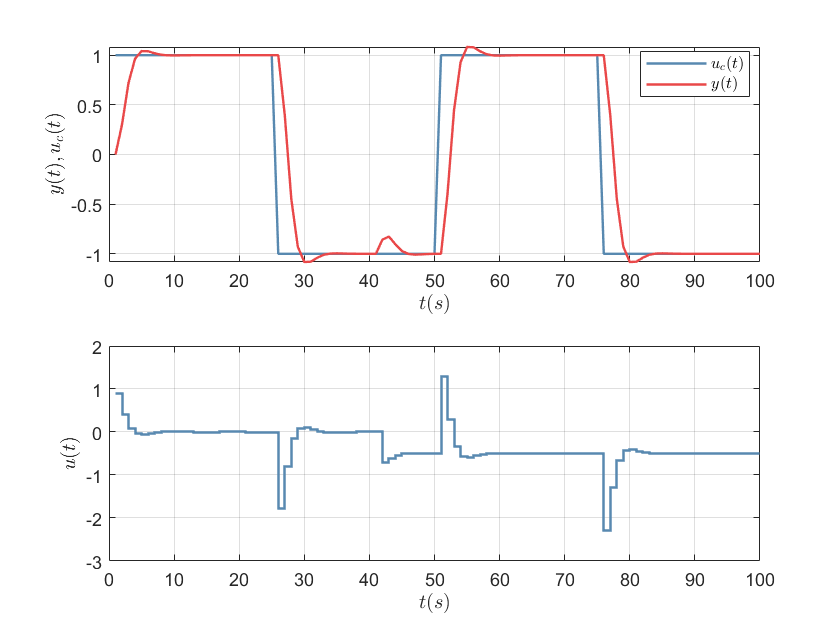

epex10_1

***Figura 13*****: ***Sinal de saída da malha fechada *$y_m(t)$*, de referência *$u_c(t)$* e de controle *$u(t)$*.*

Observando a Figura 13 e comparando-a com a Figura 11, é evidente que a ação integral reduz a perturbação imposta por $v(t)$ no sinal de controle $u(t)$ logo após $t=40$. 

Assim como no Exemplo 9 , para a estimativa de parâmetros por mínimos quadrados, o fator de esquecimento foi definido como $\lambda=0.98$. Na Figura 14 estão apresentadas as estimativas para os parâmetros $\hat{\theta} = [a_1\, a_2\, b_0\, b_1]$ do modelo estimado empregando RLS.

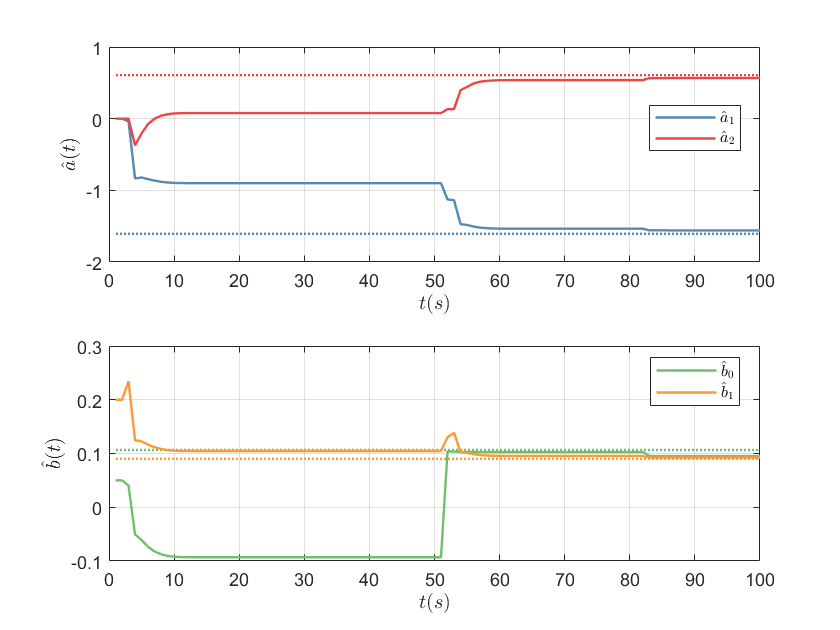

epex10_2

***Figura 14*****: ***Estimativa dos parâmetros *$\hat{\theta}$ *do processo *$H(q)$*. *

Observando a Figura 14, é evidente que, com a modificação do estimador e controlador pelo fator $A_d$, os parâmetros estimados para os coeficientes dos polinômios $A$ e $B$ convergem para os valores reais. Desse modo, é possível afirmar que houve a rejeição da perturbação $v(t)$ imposta sobre o sinal de controle.

### Exercício proposto: Observador-estimador com ação integal

Considere um sistema descrito por:


$$\rho x=Ax+Bu$$



$$y=Cx$$


para $x$ e $u$ o vetor de estados e de entradas do sistema, respectivamente. Esse modelo pode ser estimado por um observador, cujo equacionamento equivale a:


$$\rho\hat{x}=A\hat{x}+Bu+J(y-\hat{y})$$



$$\hat{y}=C\hat{x}$$


Subtraindo $\rho\hat{x}$ de $\rho x$, obtém-se o erro $\rho\tilde{x}=(A-JC)\tilde{x} = (A-JC)(x-\hat{x})$. Logo, a lei de controle para a malha fechada é expressa por:


$$u = -k_c\hat{x}+k_ix_i=-k_p(x-\tilde{x})+k_ix_i$$
 

para $\dot{x_i} = v-y=v-Cx$ para $v$ o sinal de referência da malha fechada. Dessa forma, o espaço de estados em malha fechada pode ser escrito por:

$\left\lbrack \begin{array}{c}
\dot{x_i } \\
\dot{x} \\
\dot{\tilde{x} } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & -C & 0\\
{\textrm{Bk}}_i  & A-{\textrm{Bk}}_p  & {\textrm{Bk}}_p \\
0 & 0 & A-\textrm{JC}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_i \\
x\\
\tilde{\;x} 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack v$, $u=-\left\lbrack \begin{array}{ccc}
-k_i  & k_p  & -k_p 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_i \\
x\\
\tilde{\;x} 
\end{array}\right\rbrack$e $y=\left\lbrack \begin{array}{ccc}
0 & C & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_i \\
x\\
\tilde{\;x} 
\end{array}\right\rbrack$

Analogamente,o  observador-estimador pode ser descrito conforme a seguinte expressão:


$$\rho\hat{x}=(A-JC)\hat{x}+Bu+Jy \therefore E_1(\rho)\hat{x} = V_1(\rho)u+ V_2(\rho)y$$


para $V_1 \left(\rho \;\right)=\textrm{Adj}{\left\lbrack \rho I-A+\textrm{JC}\right\rbrack }^{-1} B$, $V_2 \left(\rho \;\right)=\textrm{Adj}{\left\lbrack \rho I-A+\textrm{JC}\right\rbrack }^{-1} J$ e $E_1 \left(\rho \;\right)=\det \left\lbrack \rho I-A+\textrm{JC}\right\rbrack$. Como $V_1(\rho)$ e $V_2(\rho)$ são vetores com $n$ elementos, para $n$ a quantidade de estados em $x$, os polinômios correspondentes possuem $(n-1)$ grau. Substituindo $\hat{x}$ na lei de controle, tem-se: 


$$u = -k_c\hat{x}+k_ix_i= -k_c\Bigg[\frac{V_1(\rho)}{E_1(\rho)}u+ \frac{V_2(\rho)}{E_1(\rho)}y\Bigg]+k_ix_i$$
 

que pode-se ser reescrito como:


$$\frac{L}{E_1}u = -\frac{P}{E_1}y+k_ix_i$$


para $P(\rho)=k_cV_2(\rho)$ e $L(\rho)=E_1(\rho)+k_cV_1(\rho)$. Analogamente à equação Diophantina, pode-se considerar que:


$$L(\rho)D(\rho)+P(\rho)N(\rho)=[E_1(\rho)+k_cV_1(\rho)]D(\rho)+[k_cV_2(\rho)]N(\rho)$$


para $\frac{N(\gamma)}{D(\gamma)} = C(\gamma I-A)^{-1}B$ os polinômios da função de transferência do processo. Substituindo $N(\gamma) = [C(\gamma I-A)^{-1}B]D(\gamma)$, obtém-se:


$$L(\rho)D(\rho)+P(\rho)N(\rho)=D(\rho)\Big\{E_1(\rho)+k_c\big[V_1(\rho)+V_2(\rho)C(\gamma I-A)^{-1}B\big]\Big\}$$


Como $V_1 \left(\rho \;\right)=E_1 \left(\rho \right){\left\lbrack \rho I-A+\textrm{JC}\right\rbrack }^{-1} B$ e $2\left(\rho \;\right)=E_1 \left(\rho \right){\left\lbrack \rho I-A+\textrm{JC}\right\rbrack }^{-1} J$, tem-se que:


$$D(\rho)\Big\{E_1(\rho)+k_c\big[V_1(\rho)+V_2(\rho)C(\rho I-A)^{-1}B\big]\Big\} = D(\rho)E_1(\rho)\Big\{1+k_c\big[(\rho I-A+JC)^{-1}B+(\rho I-A+JC)^{-1}JC(\rho I-A)^{-1}B\big]\Big\} $$


Evidenciando o fator $B$ e $(\rho I-A+JC)^{-1}$, obtém-se:


$$D(\rho)E_1(\rho)\Big\{1+k_c\big[(\rho I-A+JC)^{-1}B+(\rho I-A+JC)^{-1}JC(\rho I-A)^{-1}B\big]\Big\}  = D(\rho)E_1(\rho)\Big\{1+k_c(\rho I-A+JC)^{-1}\big[I+JC(\rho I-A)^{-1}\big]B\Big\} $$


Em seguida, evidenciando o fator $(\rho I-A)^{-1}$, conclui-se:


$$ D(\rho)E_1(\rho)\Big\{1+k_c(\rho I-A+JC)^{-1}\big[I+JC(\rho I-A)^{-1}\big]B\Big\}  =  D(\rho)E_1(\rho)\Big\{1+k_c(\rho I-A+JC)^{-1}\big[(\rho I-A)+JC\big](\rho I-A)^{-1}B\Big\} $$



$$= D(\rho)E_1(\rho)\Big\{1+k_c(\rho I-A)^{-1}B\Big\} = D(\rho)E_1(\rho)\det\Big\{I+(\rho I-A)^{-1}Bk_c\Big\} = D(\rho)E_1(\rho)\det\Big\{(\rho I-A)^{-1}\Big\}\det\Big\{\rho I-A+Bk_c\Big\}$$


Logo, encontra-se que:


$$L(\rho)D(\rho)+P(\rho)N(\rho) = E_1(\rho)E_2(\rho)$$


para $D(\rho) = \det{(\rho I-A)}$ e $E_2(\rho) = \det{(\rho I-A+Bk_c)}$. Nesse caso, $v$ é escolhido como $v=\frac{G}{E_1}(y^\ast-y)$.

Esse algoritmo para observador-estimador com ação integral pode ser simulado com diagrama Simulink abaixo.

graham

## **Referências bibliográficas**

[1] K. ASTRÖM, B. WITTENMARK. **Real-time Parameter Estimation**. CRC Press, 2000. ISBN 0486462781.